clear;

# BHZ 3D hex

## useful tool

s_0   = pauli_matric(0)  ;  s_x = pauli_matric(1);  s_y =  pauli_matric(2) ;  s_z = pauli_matric(3);
sigma_0 = pauli_matric(0);sigma_x =  pauli_matric(1);sigma_y =  pauli_matric(2);sigma_z = pauli_matric(3);
tau_0   = pauli_matric(0);  tau_x =  pauli_matric(1);  tau_y =  pauli_matric(2);  tau_z = pauli_matric(3);

syms C0 C1 C2 real;
syms M0 M1 M2 real;
syms A0 A1 A2 B real;
syms k_x k_y k_z real;
%
M       = -M0+M2*(k_x^2+k_y^2)+M1*(k_z^2);
E0k     = C0+C2*(k_x^2+k_y^2)+C1*(k_z^2);
A       = A0+A2*(k_x^2+k_y^2)+A1*(k_z^2);
k_plus  = k_x + 1i* k_y;
k_minus = k_x - 1i* k_y;
%
BHZ = HK(4,3);
%
BHZ = BHZ ...
    +Term(A*k_x ,sigma_z*tau_x )...
    +Term(A*k_y ,sigma_0*tau_y )...
    +Term(E0k   ,sigma_0*tau_0 )...
    +Term(M     ,sigma_0*tau_z )...
    +Term(B*k_z*(k_x^2-k_y^2),sigma_x*tau_x )...
    +Term(2*B*k_z*(k_x*k_y),sigma_y*tau_x )...
    ;

Setting 4/4 term into HK ...


Setting 4/4 term into HK ...


Setting 4/4 term into HK ...


Setting 4/4 term into HK ...


Setting 2/2 term into HK ...


Setting 1/1 term into HK ...


C0     = 0;
A1     =  0    ;
A2     =  0    ;
BHZ = BHZ.Subsall('sym');

% unit eV 
M0     = -1   ;
%M0     = -0.25   ;
% unit eV Ang
A0      =  1      ;
%B      =  4.1      ;
% unit eV Ang^2
C1     =  0     ;
C2     =  0     ;
M1     =  -0.5      ;
M2     =  -0.5  ;
B     =  1   ;
% unit    Ang
a      =  1        ;
b      =  1       ;
c      =  1        ;
BHZ = BHZ <'POSCAR_6';
BHZ_TB= BHZ.kp2TB();

% bandplot
BHZ_TB_n = BHZ_TB.Subsall();
BHZ_TB_n = BHZ_TB_n <'KPOINTS';
BHZ_TB_super_n = BHZ_TB_n.supercell_hr([1,0,0;1,2,0;0,0,1]);

Search done; begin set hoppings
We can improve the perfomance later
Generate process: SUPERCELL(1,2) NRPT(1,21) RUNINGTIME: 0.069000 s.
Generate process: SUPERCELL(1,2) NRPT(2,21) RUNINGTIME: 0.154000 s.
Generate process: SUPERCELL(1,2) NRPT(3,21) RUNINGTIME: 0.213000 s.
Generate process: SUPERCELL(1,2) NRPT(4,21) RUNINGTIME: 0.275000 s.
Generate process: SUPERCELL(1,2) NRPT(5,21) RUNINGTIME: 0.347000 s.
Generate process: SUPERCELL(1,2) NRPT(6,21) RUNINGTIME: 0.404000 s.
Generate process: SUPERCELL(1,2) NRPT(7,21) RUNINGTIME: 0.459000 s.
Generate process: SUPERCELL(1,2) NRPT(8,21) RUNINGTIME: 0.517000 s.
Generate process: SUPERCELL(1,2) NRPT(9,21) RUNINGTIME: 0.565000 s.
Generate process: SUPERCELL(1,2) NRPT(10,21) RUNINGTIME: 0.617000 s.
Generate process: SUPERCELL(1,2) NRPT(11,21) RUNINGTIME: 0.679000 s.
Generate process: SUPERCELL(1,2) NRPT(12,21) RUNINGTIME: 0.741000 s.
Generate process: SUPERCELL(1,2) NRPT(13,21) RUNINGTIME: 0.813000 s.
Generate process: SUPERCELL(1,2) NRPT(14,21)

EIGENCAR = BHZ_TB_super_n.EIGENCAR_gen();
bandplot(EIGENCAR,[-2,2],'title',"HODSM-HEX-Super");
% BHZ_TB_super_n.orbL = zeros(8,3);


%[BFCAR,~,klist_l] = BHZ_TB_super_n.WilsonLoop('knum_int',31,'kstart',[0,0,0.1],'kevolution',[1,0,0],'kintegral',[0,1,0]);
 [BFCAR,~,klist_l] = BHZ_TB_super_n.WilsonLoop('knum_int',31,'kstart',[0,0,0.1],'kevolution',[0,1,0],'kintegral',[1,0,0]);
[fig2,ax2] = vasplib.WilsonLoopPlot((BFCAR),klist_l,'LineSpec','-o');

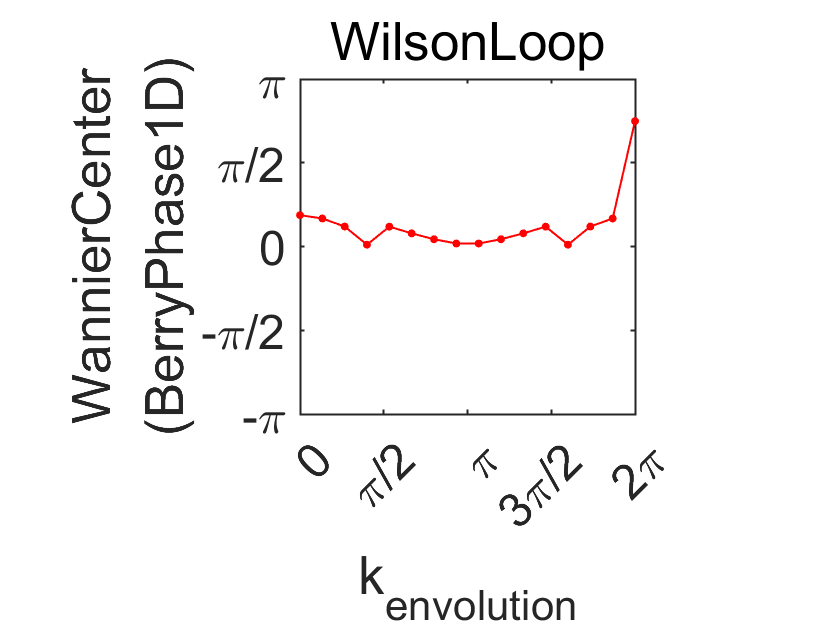

[nested_BFCAR,~,nested_klist_l] = BHZ_TB_super_n.nested_WilsonLoop('knum_evol',16,'kevolution',[1,0,0]/sqrt(3),'kintegral',[0,1,0],"nested_BAND_index",[1,2]);
[fig2,ax2] = vasplib.WilsonLoopPlot(abs(nested_BFCAR),nested_klist_l,'LineSpec','-o','Color','r');

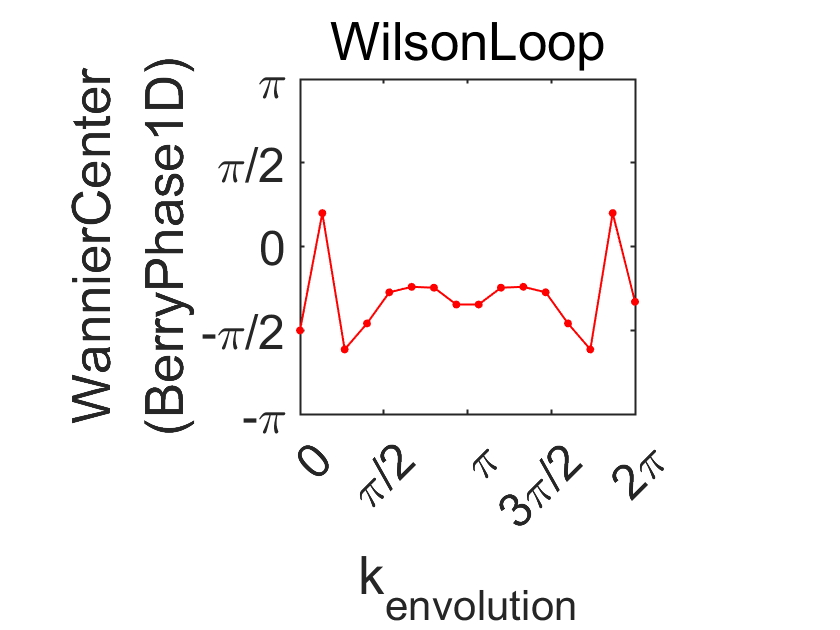

[nested_BFCAR,~,nested_klist_l] = BHZ_TB_super_n.nested_WilsonLoop('knum_evol',16,'kevolution',[0,1,0]/sqrt(3),'kintegral',[1,0,0],"nested_BAND_index",[1,2]);
[fig2,ax2] = vasplib.WilsonLoopPlot((nested_BFCAR),nested_klist_l,'LineSpec','-o','Color','r');

test = 1

test =      1


Gen (1/3) NRPT z 
1 th NRPT z ---- Gen (1/3) NRPT y 
1 th NRPT z ---- 1 th NRPT y ---- Gen (1/2) NRPT x 
1 th NRPT z ---- 1 th NRPT y ---- Gen (2/2) NRPT x 
1 th NRPT z ---- Gen (2/3) NRPT y 
1 th NRPT z ---- 2 th NRPT y ---- Gen (1/3) NRPT x 
1 th NRPT z ---- 2 th NRPT y ---- Gen (2/3) NRPT x 
1 th NRPT z ---- 2 th NRPT y ---- Gen (3/3) NRPT x 
1 th NRPT z ---- Gen (3/3) NRPT y 
1 th NRPT z ---- 3 th NRPT y ---- Gen (1/2) NRPT x 
1 th NRPT z ---- 3 th NRPT y ---- Gen (2/2) NRPT x 
Gen (2/3) NRPT z 
2 th NRPT z ---- Gen (1/3) NRPT y 
2 th NRPT z ---- 1 th NRPT y ---- Gen (1/2) NRPT x 
2 th NRPT z ---- 1 th NRPT y ---- Gen (2/2) NRPT x 
2 th NRPT z ---- Gen (2/3) NRPT y 
2 th NRPT z ---- 2 th NRPT y ---- Gen (1/3) NRPT x 
2 th NRPT z ---- 2 th NRPT y ---- Gen (2/3) NRPT x 
2 th NRPT z ---- 2 th NRPT y ---- Gen (3/3) NRPT x 
2 th NRPT z ---- Gen (3/3) NRPT y 
2 th NRPT z ---- 3 th NRPT y ---- Gen (1/2) NRPT x 
2 th NRPT z ---- 3 th NRPT y ---- Gen (2/2) NRPT x 
Gen (3/3) NRPT z 
3 th NRP

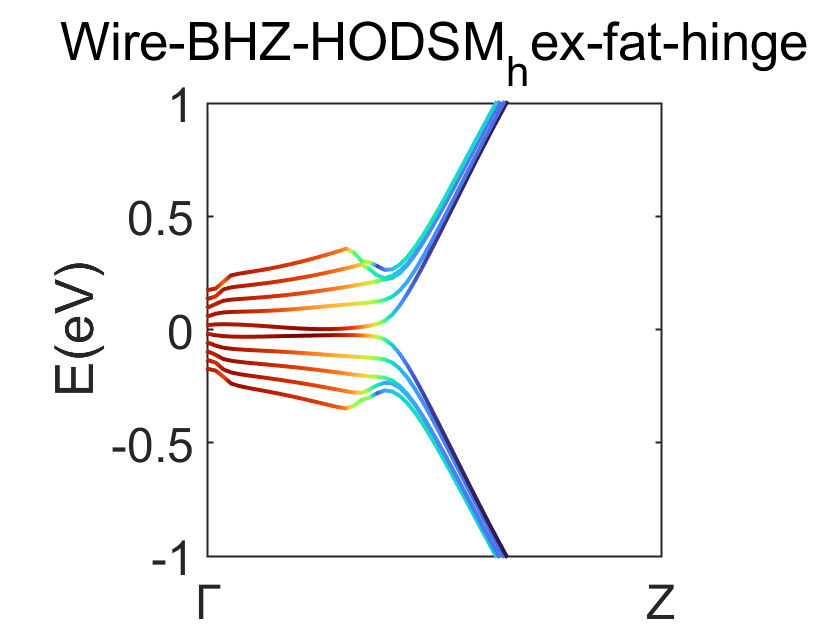

if test  == 1
    vacuum_mode = 1;
    kpoints = [0 0 1/6];
    Nslab = [20 20 1];
    np = 1;
    norb_enforce = 20;
    fermi = 0;
    KPOINTS_wire = 'KPOINTS_wire';
    cmap = turbo;
    fontname = 'Helvetica';
    [EIGENCAR_wire,orb_list,WEIGHTCAR,klist_l,kpoints_l,kpoints_name]  = BHZ_TB_super_n.EIGENCAR_gen_wire(Nslab,fermi,norb_enforce,KPOINTS_wire,vacuum_mode,np);
     pbandplot(WEIGHTCAR,EIGENCAR_wire,[-1,1],'Wire-BHZ-HODSM_hex-fat-hinge',cmap,klist_l,kpoints_l,kpoints_name);

end